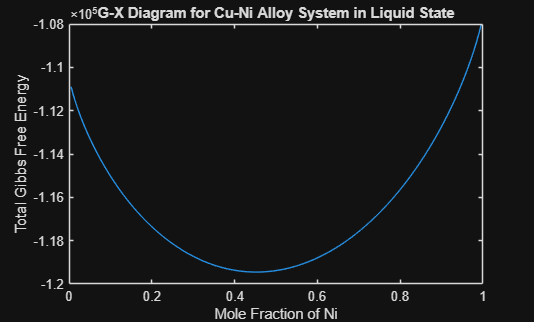

%Expterment No 6: Determination of Chemical Potential for Cu-Ni Alloy system in Liquid State
% Name of programmer- Sahil Patra (124MM0055)
clc
clear all
close all
R=8.314; % Universal Gas Constant in J/mol/K
T=1800; % Temperature of alloy in Kelvin
X_Ni = [0:0.005:1]; % Mole Fraction of Nickel
X_Cu = 1-X_Ni; % Mole Fraction of Copper
% Calculastion of Entropy
Del_S= -R*(X_Ni.*log(X_Ni)+X_Cu.*log(X_Cu));
G_TS= -T*Del_S;
%Gibbs Free Energy Calculation for Pure Copper (Data Source: SGTE,1991)
if T>= 298.15 && T<= 1358
    g0_Cu_L= 5194.277 + 120.973331*T - 24.112392*T*log(T) - 2.65684*10^(-3)*T^2 + 0.129223*10^(-6)*T^3 + 52478*T^(-1) - 584.89*10^(-23)*T^7;
end
if T>1358 && T<3200
    g0_Cu_L= -46.545 + 173.881484*T - 31.38*T*log(T);
end


%Gibbs Free Energy Calculation for Pure Nickel (Data Source: SGTE,1991)
if T>= 298.15 && T<= 1728
    g0_Ni_L= 11235.527 + 108.457*T - 22.096*T*log(T) - 4.8407*10^(-3)*T^2 - 382.318*10^(-23)*T^7;
end
if T>1728 && T<3000
    g0_Ni_L= -9549.817 + 268.597977*T - 43.1*T*log(T); 
end
% Calculation of Total Gibbs Free Energy 
G_L=X_Cu*g0_Cu_L+X_Ni*g0_Ni_L+G_TS;
plot(X_Ni,G_L)
xlabel("Mole Fraction of Ni")
ylabel("Total Gibbs Free Energy")
title("G-X Diagram for Cu-Ni Alloy System in Liquid State")


% Calculation for chemical Potential for Two Points
X1= 0.2;
X2=0.6;
y1= G_L(41);
y2=G_L(121);
dy=diff(G_L);
dx=diff(X_Ni);
m = dy./dx

m = 1.0e+04 *

       NaN   -7.0536   -6.2630   -5.7469   -5.3611   -5.0521   -4.7938   -4.5716   -4.3762   -4.2017   -4.0440   -3.8998   -3.7670   -3.6438   -3.5287   -3.4208   -3.3191   -3.2228   -3.1314   -3.0443   -2.9612   -2.8815   -2.8051   -2.7315   -2.6607   -2.5922   -2.5261   -2.4620   -2.3998   -2.3394   -2.2807   -2.2236   -2.1679   -2.1136   -2.0606   -2.0087   -1.9580   -1.9084   -1.8598   -1.8121   -1.7653   -1.7194   -1.6743   -1.6300   -1.5864   -1.5434   -1.5012   -1.4596   -1.4185   -1.3781


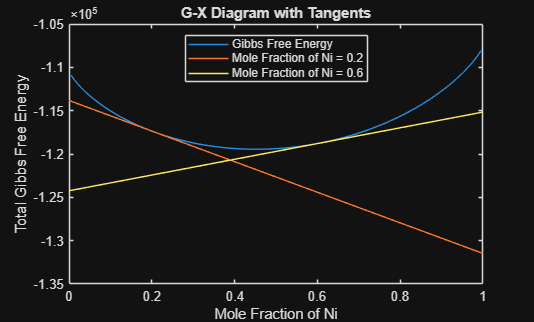

y_1 = y1+m(41)*(X_Ni-0.2);
y_2 = y2 + m(121)*(X_Ni-0.6);
plot(X_Ni,G_L)
hold on
plot(X_Ni,y_1)
plot(X_Ni,y_2)
xlabel("Mole Fraction of Ni")
ylabel("Total Gibbs Free Energy")
legend('Gibbs Free Energy', 'Mole Fraction of Ni = 0.2', 'Mole Fraction of Ni = 0.6',Location='north');
title("G-X Diagram with Tangents")
hold off 

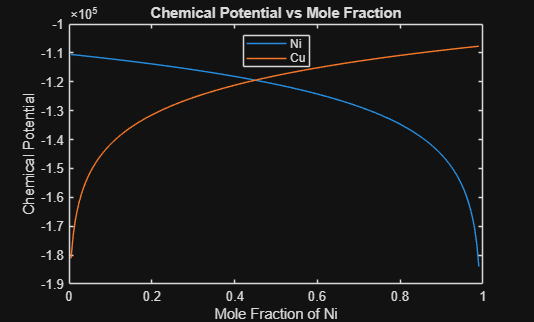

% Calculation for Chemical Potential 
n= length(X_Ni);
for i= 2:n-2
    x1=X_Ni(i);
    y1=G_L(i);
    mu_Cu(i)=y1+m(i)*(0-x1);
    mu_Ni(i) = y1 + m(i) * (1 - x1);
end
plot(X_Ni([2:n-2]),mu_Cu([2:n-2]))
hold on 
plot(X_Ni([2:n-2]),mu_Ni([2:n-2]))
title("Chemical Potential vs Mole Fraction")
xlabel("Mole Fraction of Ni")
ylabel("Chemical Potential")
legend("Ni","Cu",Location="north")
hold off

% Calculating Activity
activity_Cu = exp((mu_Cu- g0_Cu_L)/ (R * T))

activity_Cu = 1.0e+03 *

    1.6030    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008


activity_Ni = exp((mu_Ni- g0_Ni_L)/ (R * T))

activity_Ni = 1.0e+03 *

    1.3241    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002


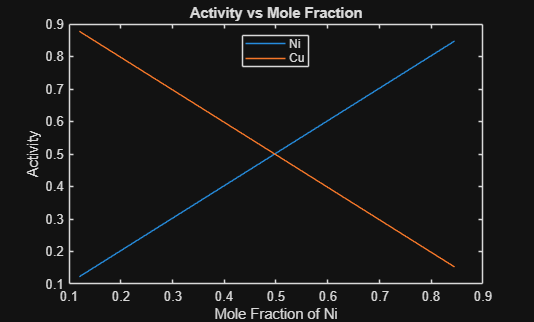

plot(X_Ni(25:170),activity_Ni(25:170))
hold on 
plot(X_Ni(25:170), activity_Cu(25:170))
xlabel("Mole Fraction of Ni")
ylabel("Activity")
title("Activity vs Mole Fraction")
legend("Ni", "Cu", Location="north")
hold off